Homework #03

## 1

1a) [show, in general]

1b)

A=[-0.7108,-2.995;1.336,-0.7892];
x0 = [-5; 2];

% finding eigenvalues
a=A(1,1);
b=A(1,2);
c=A(2,1);
d=A(2,2);
disp('eigenvalues:')

eigenvalues:


lambda = [(a+d)/2+( ((a+d)/2).^2 - ((a.*d) - (b.*c)) )^(1/2), 0; ...
    0, (a+d)/2-( ((a+d)/2).^2 - ((a.*d) - (b.*c)) )^(1/2)];
lambda_vec = [lambda(1,1) lambda(2,2)]

lambda_vec =   -0.7500 + 1.9999i  -0.7500 - 1.9999i



% finding eigenvectors
e_vecs = zeros(length(lambda_vec), 2);
for i=1:1:length(lambda_vec)
    e_space = A-lambda_vec(1,i)*eye(2);
    e_vecs(:, i) = null(e_space);
end
disp('eigenvectors:')

eigenvectors:


disp(e_vecs)

   0.8316 + 0.0000i   0.8316 + 0.0000i
   0.0109 - 0.5553i   0.0109 + 0.5553i




% finding the a constant based on x0
disp('the a constant:')

the a constant:


a_const = e_vecs^(-1)*x0;
a_const=a_const.'

a_const =   -3.0063 + 1.8598i  -3.0063 - 1.8598i


1c)

t=2.0

t = 2


% diag turns elements of vector into diagonal elements
expm_A2=e_vecs*diag(exp(lambda_vec*t))*e_vecs^(-1)

expm_A2 =   -0.1492 + 0.0000i   0.2529 + 0.0000i
  -0.1128 - 0.0000i  -0.1426 + 0.0000i



disp(expm(A*t))

   -0.1492    0.2529
   -0.1128   -0.1426



The calculated sum is indeed equal to Matlab's expm output

disp('solution at t=2:')

solution at t=2:


disp(expm_A2*x0)

   1.2516 - 0.0000i
   0.2789 + 0.0000i



1d) [draw schematically?]

figure
hold on
[X,Y] = meshgrid(-10:1:10,-10:1:10);
X=X(:).';
Y=Y(:).';
gradient = A*[X;Y];
U = gradient(1,:)

U =    37.0580   34.0630   31.0680   28.0730   25.0780   22.0830   19.0880   16.0930   13.0980   10.1030    7.1080    4.1130    1.1180   -1.8770   -4.8720   -7.8670  -10.8620  -13.8570  -16.8520  -19.8470  -22.8420   36.3472   33.3522   30.3572   27.3622   24.3672   21.3722   18.3772   15.3822   12.3872    9.3922    6.3972    3.4022    0.4072   -2.5878   -5.5828   -8.5778  -11.5728  -14.5678  -17.5628  -20.5578  -23.5528   35.6364   32.6414   29.6464   26.6514   23.6564   20.6614   17.6664   14.6714


V = gradient(2,:)

V =    -5.4680   -6.2572   -7.0464   -7.8356   -8.6248   -9.4140  -10.2032  -10.9924  -11.7816  -12.5708  -13.3600  -14.1492  -14.9384  -15.7276  -16.5168  -17.3060  -18.0952  -18.8844  -19.6736  -20.4628  -21.2520   -4.1320   -4.9212   -5.7104   -6.4996   -7.2888   -8.0780   -8.8672   -9.6564  -10.4456  -11.2348  -12.0240  -12.8132  -13.6024  -14.3916  -15.1808  -15.9700  -16.7592  -17.5484  -18.3376  -19.1268  -19.9160   -2.7960   -3.5852   -4.3744   -5.1636   -5.9528   -6.7420   -7.5312   -8.3204


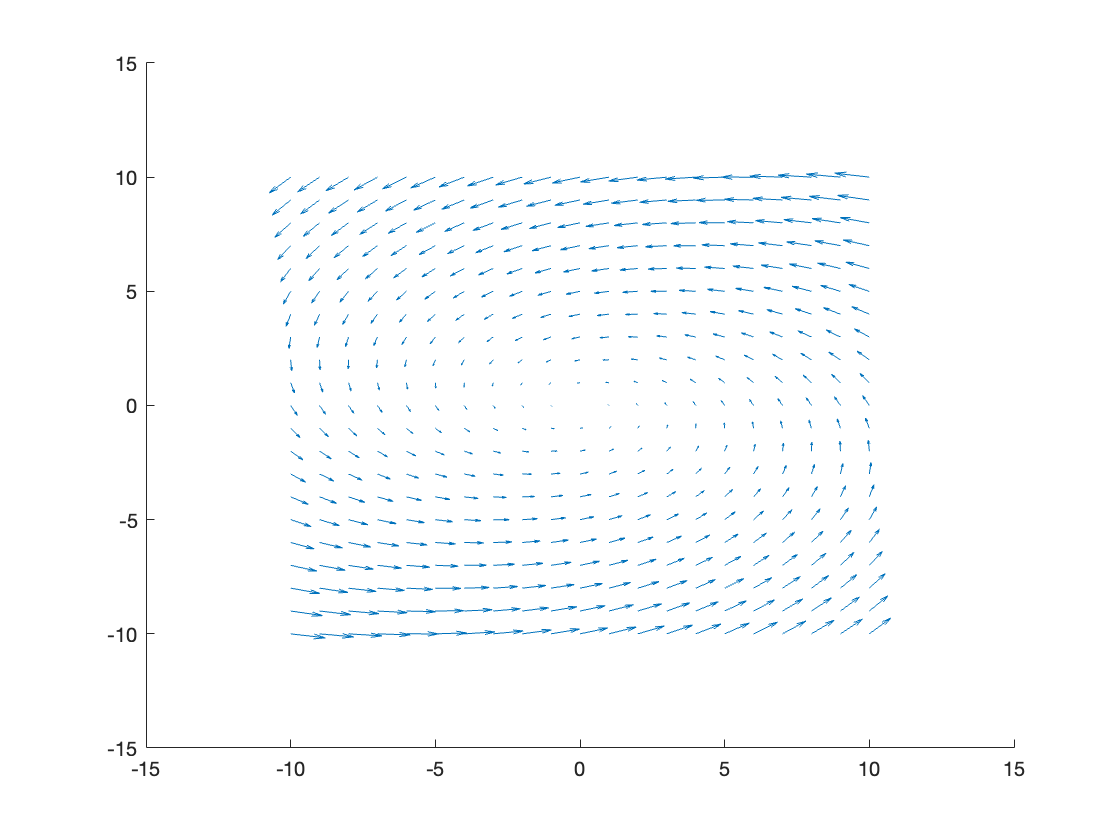


% [] can I draw with matlab?
q = quiver(X,Y,U,V);
hold off

1e) So $\frac{dx}{dt}=ax+by$

then $\frac{d^2x}{dt^2}=a\frac{dx}{dt}+b\frac{dy}{dt}$

and if $\frac{dy}{dt}=cx+dy$

then $\frac{d^2x}{dt^2}=a\frac{dx}{dt}+b(cx+dy)$

disp(['x''''=' num2str(a) '(' num2str(a) 'x+' num2str(b) 'y)+'...
    num2str(b) '(' num2str(c) 'x+' num2str(d) 'y)' ])

x''=-0.7108(-0.7108x+-2.995y)+-2.995(1.336x+-0.7892y)


1fi)

t=2.0;
x2_sad=[-2; -2];

disp('initial conditions based on x2=[-2;-2]:')

initial conditions based on x2=[-2;-2]:


x0_sad=expm_A2^(-1)*x2_sad

x0_sad =   15.8843 - 0.0000i
   1.4615 - 0.0000i


1fii) 

[**Did they have a chance to begin with. . . ? That is, would different initial mutual feelings lead to a more favorable state on that particular anniversary?]**

**Does the future look any brighter?**

No, the eigenvalues have negative real parts

disp(lambda_vec)

  -0.7500 + 1.9999i  -0.7500 - 1.9999i



So they will always eventually end up at 0, 0

1gi) 

t=0:1:15

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


x_sad=zeros(2,15);
for i=0:1:15
    x_sad(:,i+1)=e_vecs*diag(exp(lambda_vec*i))*e_vecs^(-1)*x0_sad;
end

figure
hold on
plot(t, x_sad(1,:), 'r')

plot(t, x_sad(2,:), 'b')

plot(t, sqrt(x_sad(1,:).^2+x_sad(2,:).^2), 'g')

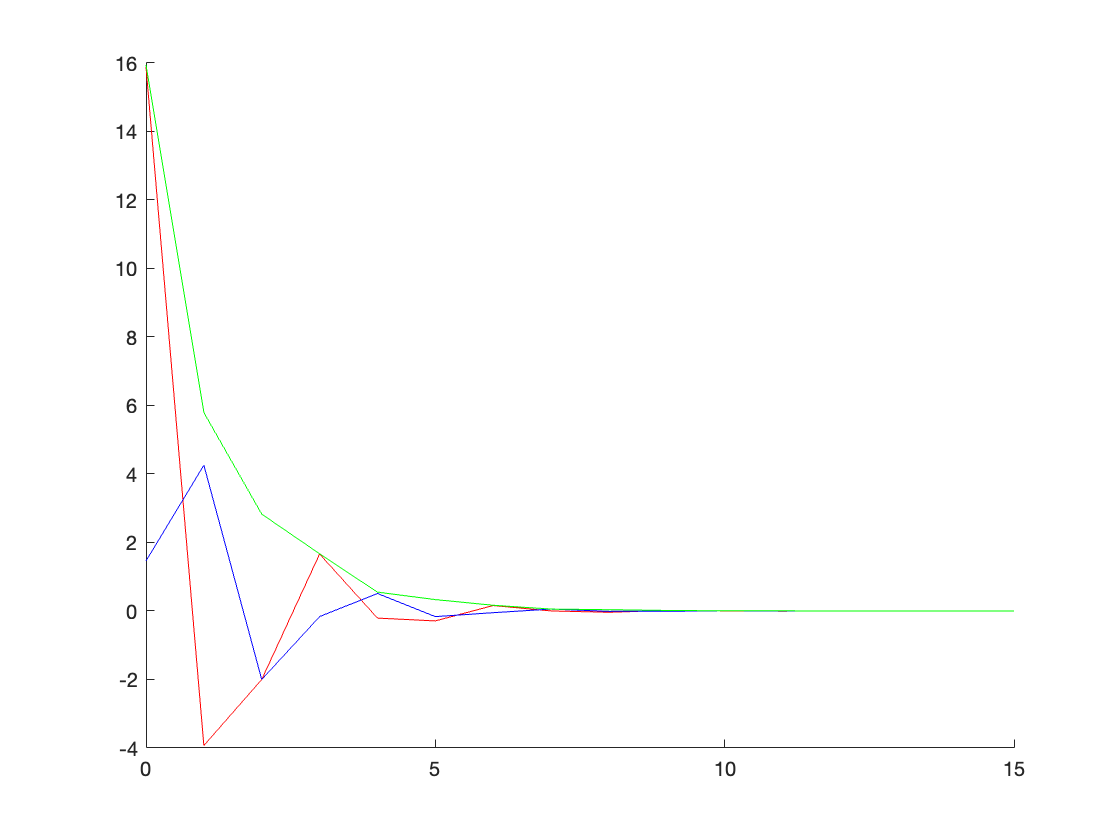

hold off

1gii)

figure
hold on
plot(x_sad(1,:), x_sad(2,:), 'm')

1giii)

[X,Y] = meshgrid(-5:1:16,-5:1:5);
X=X(:).';
Y=Y(:).';
gradient = A*[X;Y];
U = gradient(1,:)

U =    18.5290   15.5340   12.5390    9.5440    6.5490    3.5540    0.5590   -2.4360   -5.4310   -8.4260  -11.4210   17.8182   14.8232   11.8282    8.8332    5.8382    2.8432   -0.1518   -3.1468   -6.1418   -9.1368  -12.1318   17.1074   14.1124   11.1174    8.1224    5.1274    2.1324   -0.8626   -3.8576   -6.8526   -9.8476  -12.8426   16.3966   13.4016   10.4066    7.4116    4.4166    1.4216   -1.5734   -4.5684   -7.5634  -10.5584  -13.5534   15.6858   12.6908    9.6958    6.7008    3.7058    0.7108


V = gradient(2,:)

V =    -2.7340   -3.5232   -4.3124   -5.1016   -5.8908   -6.6800   -7.4692   -8.2584   -9.0476   -9.8368  -10.6260   -1.3980   -2.1872   -2.9764   -3.7656   -4.5548   -5.3440   -6.1332   -6.9224   -7.7116   -8.5008   -9.2900   -0.0620   -0.8512   -1.6404   -2.4296   -3.2188   -4.0080   -4.7972   -5.5864   -6.3756   -7.1648   -7.9540    1.2740    0.4848   -0.3044   -1.0936   -1.8828   -2.6720   -3.4612   -4.2504   -5.0396   -5.8288   -6.6180    2.6100    1.8208    1.0316    0.2424   -0.5468   -1.3360


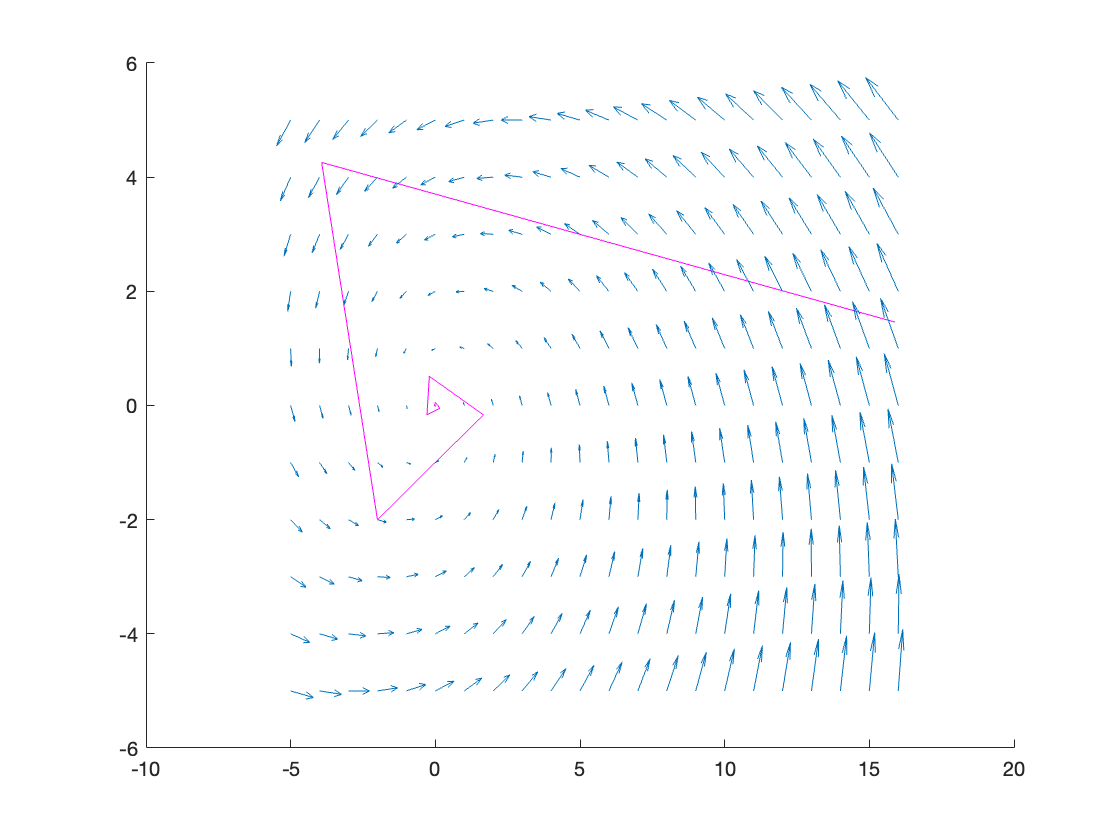


q = quiver(X,Y,U,V);
hold off

## 2

2a)

A=[ -64.0859, -22.6535;
177.346, 62.6859];

% finding eigenvalues
a=A(1,1);
b=A(1,2);
c=A(2,1);
d=A(2,2);
disp('eigenvalues:')

eigenvalues:


lambda_vec = [(a+d)/2+( ((a+d)/2).^2 - ((a.*d) - (b.*c)) )^(1/2), 0;...
    0, (a+d)/2-( ((a+d)/2).^2 - ((a.*d) - (b.*c)) )^(1/2)]

lambda_vec =    -0.1855         0
         0   -1.2145



% finding eigenvectors
e_vecs = zeros(length(lambda_vec), 2);
for i=1:1:length(lambda_vec)
    e_space = A-lambda_vec(i,i)*eye(2);
    e_vecs(:, i) = null(e_space);
end
disp('eigenvectors:')

eigenvectors:


disp(e_vecs)

    0.3341    0.3390
   -0.9425   -0.9408



Since $Ax=\sum_{i=1}^{n} c_i e_i e^{\lambda t}$  and the eigenvalues are negative, $e^{\lambda t}$ and $Ax$ overall will go towards 0.

The two eigenvectors are also very close to each other and linearly dependent on each other.

2b)